gas = Solution('gri30.yaml','gri30');
N = nSpecies(gas);
iCH4 = speciesIndex(gas, 'CH4');
iC2H6 = speciesIndex(gas, 'C2H6');
iC3H8 = speciesIndex(gas, 'C3H8');
iCO2 = speciesIndex(gas, 'CO2');
iO2 = speciesIndex(gas, 'O2');
iN2 = speciesIndex(gas, 'N2');
M = molecularWeights(gas);

xfuel = zeros(1, N);
xfuel(iCH4) = 0.907;
xfuel(iC2H6) = 0.036;
xfuel(iC3H8) = 0.019;
xfuel(iCO2) = 0.010;
xfuel(iN2) = 0.018;
xfuel(iO2) = 0.010;

set(gas, 'T', 300, 'P', 101325, 'X', xfuel);

air = Solution('gri30.yaml','gri30');
N = nSpecies(air);
iO2 = speciesIndex(air, 'O2');
iN2 = speciesIndex(air, 'N2');
xair = zeros(1, N);
xair(iN2) = 0.79;
xair(iO2) = 0.21;
set(air, 'T', 300, 'P', oneatm, 'X', xair);

fuel_to_air = 0.0390;
W_in= 0;
W_out = 0;


%Stage 1 - Two Compressors

T_fuel_comp = zeros(1, 1);
T_air_comp = zeros(1, 1);
s_fuel_comp = zeros(1, 1);
s_air_comp = zeros(1, 1);

set(gas, 'T', 300, 'P', oneatm, 'X', xfuel);

Pi = oneatm;
P_gas_2 = 40*oneatm;
P_air_2 = 20*oneatm;
delta = 0.01*oneatm;
P_tracker = Pi;
epsilon = 0.9;

h_gas_1 = enthalpy_mass(gas);
h_air_1 = enthalpy_mass(air);

h_gas = enthalpy_mass(gas);
h_air = enthalpy_mass(air);

T_fuel_comp(1) = temperature(gas);
s_fuel_comp(1) = entropy_mass(gas);

%Fuel
while P_tracker < P_gas_2
    s_initial = entropy_mass(gas);
    h_initial = enthalpy_mass(gas);
    P_tracker = P_tracker + delta;

    set(gas, 'P', P_tracker, 'S', s_initial);

    h_final_ideal = enthalpy_mass(gas);
    W_real = (h_final_ideal-h_initial)/epsilon;
    h_final_actual = h_initial+W_real;

    set(gas, 'P', P_tracker, 'H', h_final_actual);
    T_fuel_comp(end + 1) = temperature(gas);
    s_fuel_comp(end + 1) = entropy_mass(gas);
    %h_gas = enthalpy_mass(gas);

end

h_gas_2 = enthalpy_mass(gas)

h_gas_2 = -3.4305e+06


W_in = W_in + (h_gas_2-h_gas_1);

set(gas, 'P', P_gas_2, 'H', h_gas_2);

T_fuel_comp(end + 1) = temperature(gas);
s_fuel_comp(end + 1) = entropy_mass(gas);
temperature(gas)

ans = 636.6833



%Air

set(air, 'T', 300, 'P', oneatm, 'X', xair);

T_air_comp(1) = temperature(air);
s_air_comp(1) = entropy_mass(air);

P_tracker = Pi;
while P_tracker < P_air_2
    s_initial = entropy_mass(air);
    h_initial = enthalpy_mass(air);
    P_tracker = P_tracker + delta;

    set(air, 'P', P_tracker, 'S', s_initial);

    h_final_ideal = enthalpy_mass(air);
    W_real = (h_final_ideal-h_initial)*epsilon;
    h_final_actual = h_initial+W_real;

    set(air, 'P', P_tracker, 'H', h_final_actual);
    T_air_comp(end + 1) = temperature(air);
    s_air_comp(end + 1) = entropy_mass(air);
    %h_gas = enthalpy_mass(gas);

end

h_air_2 = enthalpy_mass(air);

W_in = W_in + (h_air_2-h_air_1);

set(air, 'P', P_air_2, 'H', h_air_2);

T_air_comp(end + 1) = temperature(air);
s_air_comp(end + 1) = entropy_mass(air);
temperature(air)

ans = 637.4890

temperature(gas)

ans = 636.6833

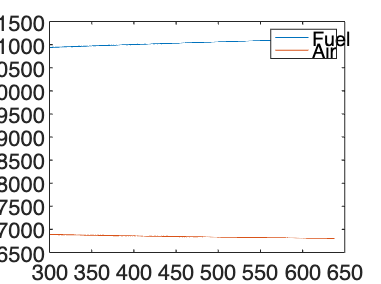

%Stage 2 - Nozzle
%makes injection stiff so fuel doesn't pulsate
%accelerates the fuel to a higher velocity which gives mixing
%pressure of fuel out of nozzle is equal to the pressure of air

T_fuel_nozzle = zeros(1,2);
s_fuel_nozzle = zeros(1,2);

T_fuel_nozzle(1) = temperature(gas);
s_fuel_nozzle(1) = entropy_mass(gas);


%For nozzle: Pressure of fuel is halved, isenthalpic process
set(gas, 'P', P_air_2, 'H', h_gas_2);

T_fuel_nozzle(2) = temperature(gas);
s_fuel_nozzle(2) = entropy_mass(gas);

temperature(air)

ans = 637.4890

temperature(gas)

ans = 636.6833

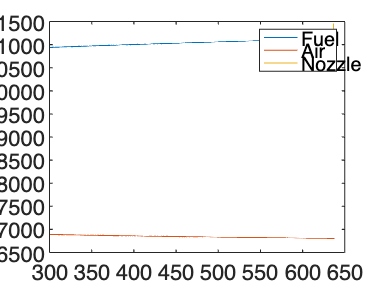

%Stage 3 - Mixer

% Air (mdot * h) + Fuel (mdog * h) = Mix (mdot * h)

T_mix_combust = zeros(1,2);
s_mix_combust = zeros(1,2);

mdot_mix = 1; %Normalize all to mix
h_air = enthalpy_mass(air);
h_fuel = enthalpy_mass(gas);

mix = Solution('gri30.yaml','gri30');
N = nSpecies(air);

iCH4 = speciesIndex(gas, 'CH4');
iC2H6 = speciesIndex(gas, 'C2H6');
iC3H8 = speciesIndex(gas, 'C3H8');
iCO2 = speciesIndex(gas, 'CO2');
iO2 = speciesIndex(gas, 'O2');
iN2 = speciesIndex(gas, 'N2');
M = molecularWeights(gas);


xmix = zeros(1, N);
% xmix(iCH4) = 0.907;
% xmix(iC2H6) = 0.036;
% xmix(iC3H8) = 0.019;
% xmix(iCO2) = 0.010;
% xmix(iN2) = 0.018 + 0.79;
% xmix(iO2) = 0.010 + 0.21;
% xmix = xmix ./2;

P_input = P_air_2 * 0.95;
%set(mix, 'H', h_air , 'P', P_input, 'X', xmix);

Nf = 0.005;
best_Nf = Nf;
best_outlet_temp = 300;
max_temp = 1600;


while Nf<0.18
    h_mix = Nf * h_fuel + (1-Nf) * h_air;
    xmix = Nf * xfuel + (1-Nf) * xair;
    set(mix, 'H', h_mix , 'P', P_input, 'X', xmix);
    equilibrate(mix, 'HP'); % Equilibrate
    T_eq = temperature(mix);
    if T_eq <= max_temp && T_eq > best_outlet_temp
        best_outlet_temp = T_eq;
        best_Nf = Nf;
    end
    Nf = Nf + 0.001;
end
best_Nf

best_Nf = 0.0430

best_outlet_temp

best_outlet_temp = 1.5826e+03


xmix = best_Nf * xfuel + (1-best_Nf) * xair;
h_mix = best_Nf * h_fuel + (1-best_Nf) * h_air;

set(mix, 'H', h_mix , 'P', P_input, 'X', xmix);

T_mix_combust(1) = temperature(mix);
s_mix_combust(1) = entropy_mass(mix);

equilibrate(mix, 'HP');

T_mix_combust(2) = temperature(mix);
s_mix_combust(2) = entropy_mass(mix);

P_mix = pressure(mix)

P_mix = 1.9252e+06

T_mix = temperature(mix)

T_mix = 1.5826e+03

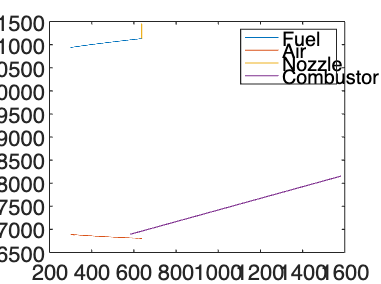

%Stage 4 - Turbine

P_tracker = pressure(mix)

P_tracker = 1.9252e+06

oneatm

ans = 101325

delta = 0.1*oneatm;
epsilon = 0.88;

T_mix_turb = zeros(1,1);
s_mix_turb = zeros(1,1);

T_mix_turb(1) = temperature(mix);
s_mix_turb(1) = entropy_mass(mix);

while P_tracker > Pi
    s_initial = entropy_mass(mix);
    h_initial = enthalpy_mass(mix);
    P_tracker = P_tracker - delta;

    set(mix, 'P', P_tracker, 'S', s_initial);

    h_final_ideal = enthalpy_mass(mix);
    W_real = (h_initial - h_final_ideal)*epsilon;
    h_final_actual = h_initial-W_real;

    set(mix, 'P', P_tracker, 'H', h_final_actual);
    T_mix_turb(end + 1) = temperature(mix);
    s_mix_turb(end + 1) = entropy_mass(mix);
    %h_gas = enthalpy_mass(gas);

end

pressure(mix)

ans = 9.1193e+04

temperature(mix)

ans = 845.3350

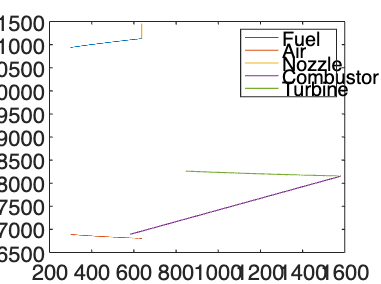

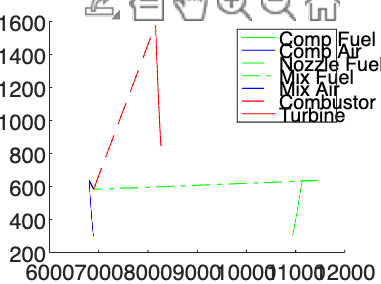

%Total T-s plot

clf
%Datasets:
% T_mix_turb
% T_mix_combust
% T_fuel_nozzle
% T_fuel_comp
% T_air_comp
%mdot air / mdot fuel = (1 - x fuel) / x fuel
% mdot mix / mdot fuel = 1 / x fuel

figure(2);
hold on;
plot(s_fuel_comp, T_fuel_comp, 'Color', [0 1 0], 'LineStyle','-')
plot(s_air_comp, T_air_comp, 'Color', [0 0 1], 'LineStyle','-')
plot(s_fuel_nozzle, T_fuel_nozzle, 'Color', [0 1 0], 'LineStyle','--')
plot([s_fuel_nozzle(end) s_mix_combust(1)], [T_fuel_nozzle(end) T_mix_combust(1)], 'Color', [0 1 0], 'LineStyle','-.')
plot([s_air_comp(end) s_mix_combust(1)], [T_air_comp(end) T_mix_combust(1)], 'Color', [0 0 1], 'LineStyle','--')
plot(s_mix_combust, T_mix_combust, 'Color', [1 0 0], 'LineStyle', '--')
plot(s_mix_turb, T_mix_turb, 'Color', [1 0 0], 'LineStyle', '-')
legend('Comp Fuel', 'Comp Air', 'Nozzle Fuel', 'Mix Fuel', 'Mix Air', 'Combustor', 'Turbine')
hold off;

%Complete combustion to major products - lean fuel
%If you burn with excess oxidizer and cool products back to 25 C and 1 atm
%Measure the amount of heat transfer and divide by the mass flow rate of
%fuel
%if all water is in vapor stage, this is lower heating value
%using cantera and that composition of the natural gas, find the heating
%value of combusting this fuel with 1 atm 25 C and combust it with extra
%oxidizer. cool it back down to 25 c and 1 atm using equilibriate.
%calculate delta H and divide by mass flow rate of fuel
% you can look up the heating value
%that is LHV. thermal effciency is different
% net work out / (product of mass of fuel * 
% rate of work out / (product of rate of fuel in and LHV)
%work is turbine out - compressor in (note its rates so its power)
% air specific work is net work (rate) / air  mass flow rate
% he recommends setting mass flow rate of air to 1 kg/s

%methane stochiometric ratio is 1/17
%since we're running lean, ratio needs to be less than that

%i solved on the rich side
%most gas turbines run on an equivalence ratio of 0.5

%what is adiabatic flame temperature ???

% LHV

fuel = Solution('gri30.yaml','gri30');
N = nSpecies(fuel);
iCH4 = speciesIndex(fuel, 'CH4');
iC2H6 = speciesIndex(fuel, 'C2H6');
iC3H8 = speciesIndex(fuel, 'C3H8');
iCO2 = speciesIndex(fuel, 'CO2');
iO2 = speciesIndex(fuel, 'O2');
iN2 = speciesIndex(fuel, 'N2');
M = molecularWeights(fuel);


xfuel = zeros(1, N);
xfuel(iCH4) = 0.907;
xfuel(iC2H6) = 0.036;
xfuel(iC3H8) = 0.019;
xfuel(iCO2) = 0.010;
xfuel(iN2) = 0.018;
xfuel(iO2) = 0.010;

xlean = 0.0390*xfuel+(1-0.0390)*xair;

set(fuel, 'Temperature', 300, 'Pressure', oneatm, 'X', xlean);

set(fuel, 'X', 'CH4:0.95, C2H6:0.04, N2:0.01'); % Example composition; adjust to your natural gas composition

H_initial = enthalpy_mass(fuel); % Enthalpy after cooling down

equilibrate(fuel, 'HP');

set(fuel, 'Temperature', 300, 'Pressure', oneatm);

H_final = enthalpy_mass(fuel); % Enthalpy after cooling down
% You need to calculate or have the initial enthalpy (H_initial) before combustion
Delta_H = H_final - H_initial;


%Best_Nf is the mole fraction of the fuel w.r.t. the mix, assuming the mass
%flow rate of air is 1kg/s, the 
mass_flow_rate_fuel = (1 / (1-best_Nf)) - 1;
LHV = -Delta_H / (mass_flow_rate_fuel) % Divide by the mass flow rate of the fuel

LHV = 1.8079e+05

% Load the Cantera gas solution with appropriate mechanism
gas = Solution('gri30.yaml', 'gri30'); % Replace with your chemical mechanism file

% Set the initial conditions and composition of the methane-air mixture
% Adjust 'X' based on your given mole fraction ratio of methane to air
set(gas, 'Temperature', 298.15, 'Pressure', oneatm, 'X', 'CH4:1,O2:2,N2:7.52');

% Calculate the initial enthalpy of the methane-air mixture
h_initial = enthalpy_mass(gas);

% Perform combustion at constant pressure
equilibrate(gas, 'HP');

% Calculate the final enthalpy of the combustion products
h_final = enthalpy_mass(gas);

% Calculate the change in enthalpy (ΔH)
Delta_H = h_final - h_initial;

% Calculate the number of moles of methane initially in the mixture
% Get the density of the gas mixture
densityGas = density(gas);

% Get the volume of the gas mixture (assuming 1 m^3 for simplicity)
% You should adjust this based on your specific system volume
volume = 1; % in cubic meters

% Calculate the total mass of the gas mixture
total_mass = densityGas * volume;

% Get the average molar mass of the gas mixture
mean_molar_mass = meanMolecularWeight(gas);

% Calculate the total number of moles in the gas mixture
total_moles = total_mass / mean_molar_mass;

% Calculate the number of moles of methane initially in the mixture
n_CH4_initial = moleFraction(gas, 'CH4') * total_moles;


% Correctly retrieve the molecular weight of methane
MW = molecularWeights(gas);
index_CH4 = speciesIndex(gas, 'CH4');
MW_CH4 = MW(index_CH4);

% Convert the moles of methane to mass
mass_CH4 = n_CH4_initial * MW_CH4;

% Calculate the LHV as the negative of ΔH per unit mass of methane
LHV = -Delta_H / mass_CH4 /10e6;

% Output the LHV
disp(['The Lower Heating Value of Methane is ', num2str(LHV), ' J/kg']);

The Lower Heating Value of Methane is 1829608.6246 J/kg
